# BASIC DECOMPOSITION-${\mathrm{SARIMA}\left(0,0,1\right)\left(0,0,1\right)}_{12}$-model

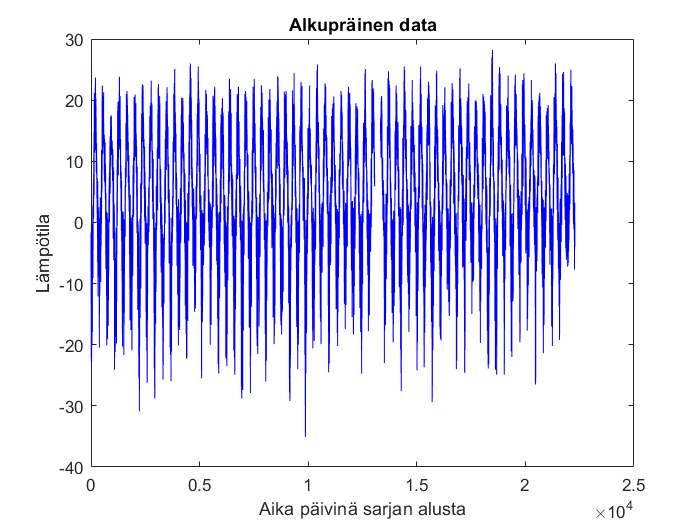

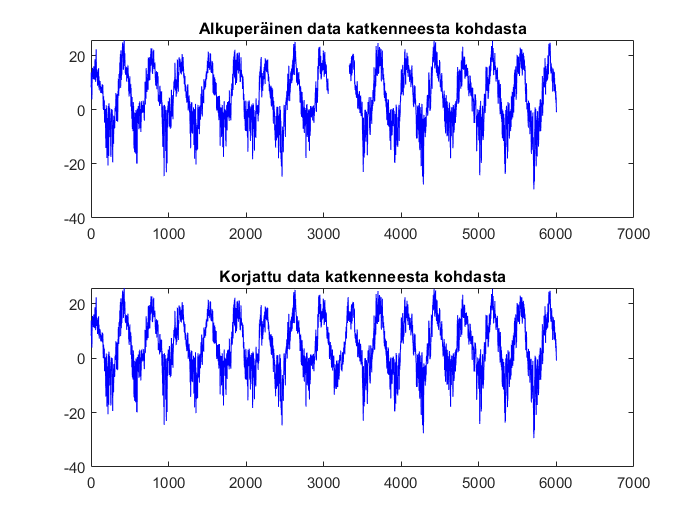

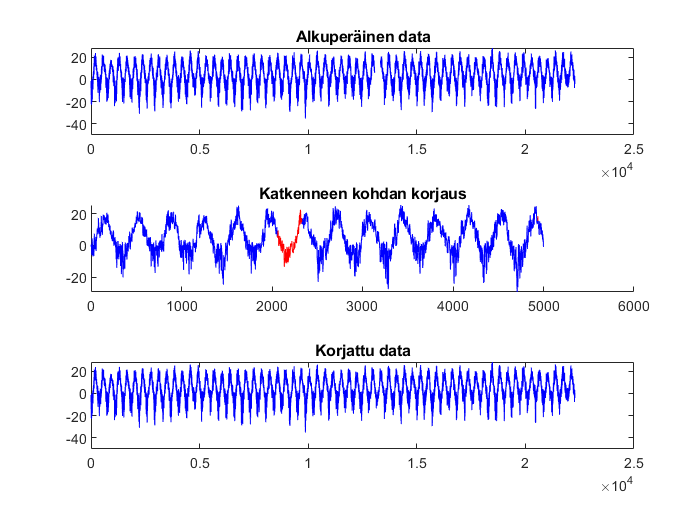

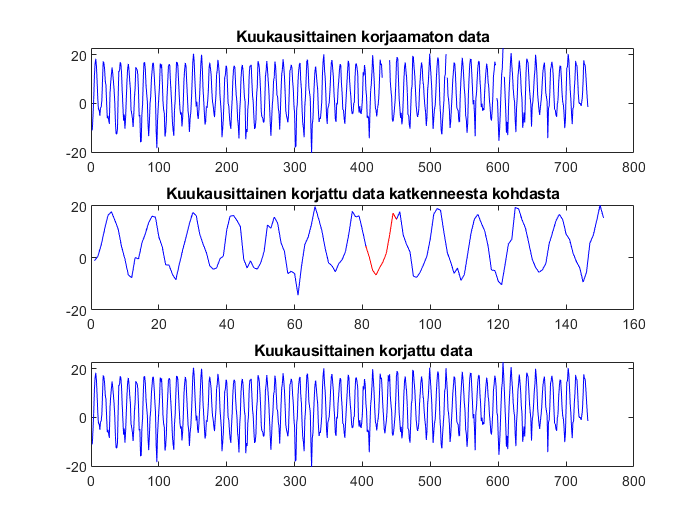

%% Down loading and sorting the data with function type code
close all;clearvars; clc;
temperature=d4ta12('Vuodenaika data Lappeenrannan lentokenttä.xlsx','Havainnot',[2 22007]);

%% Validation selecting and zoomed plotting oreder
% 59 years chosen for model creating
a = 59;
% 2 years chosen for forecast validation
a_valid = 61-a;
% plotting order, 10 yeras
a2 = 10;

% data for model creation
temp = temperature(1:a*12);


### Decomposition (additive):


$$\mathit{\mathbf{timeseries}}=\mathit{\mathbf{trend}}+\mathit{\mathbf{seasonality}}+\mathit{\mathbf{white}}\;\mathit{\mathbf{noise}}$$


white noise will be modeled by *ARIMA*-model

## Removing the possible trend

%% DECOMPOSITION-SARMA (trend)
Y = temp; % auxiliar variable Y
% creating constant and index for x-axis
X = [ones(length(temp),1) [1:length(temp)]'];

% Manual ortogonal projection calculation
% Xb=Y
% X'Xb=X'Y
% b=(X'X)^(-1)X'Y

% b-values, first is constant, y-label intersection point, second one is
% slope cofficient
b = X\Y

b =     2.9860
    0.0032


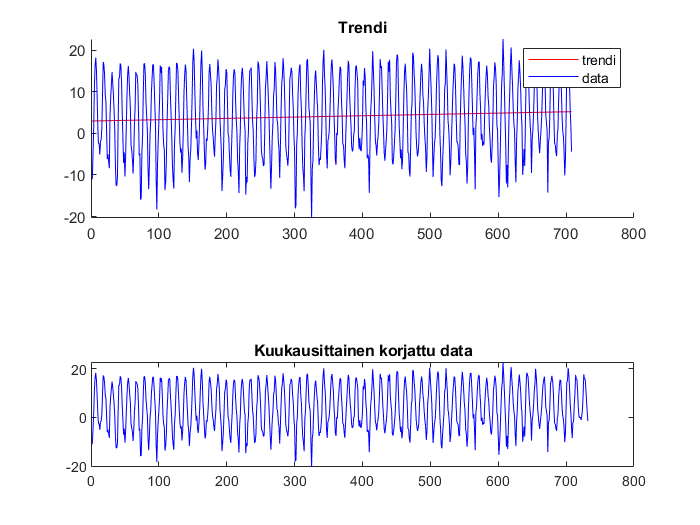

% projection=trend=Yfit
trend = X*b;

% plotting the trend
figure(4)
subplot(2,1,1)
hold on
plot(trend,'r')
plot(temp,'b')
title('Trendi')
legend('trendi','data')

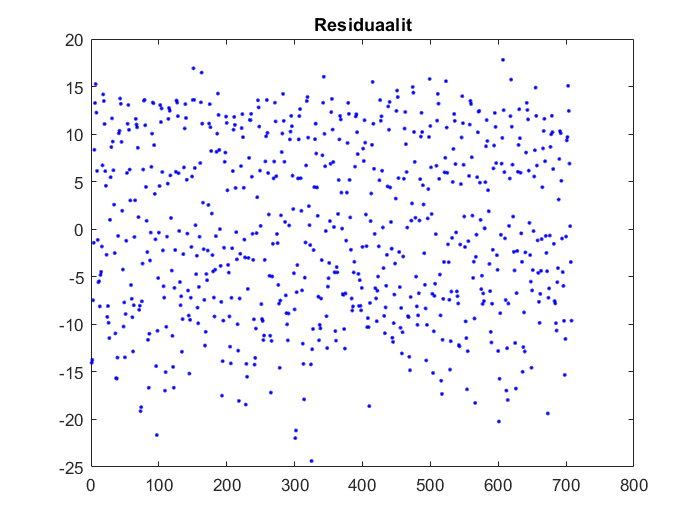


% residuals of the trend
e_trend = temp-trend;
figure
plot(e_trend,'b.')
title('Residuaalit')

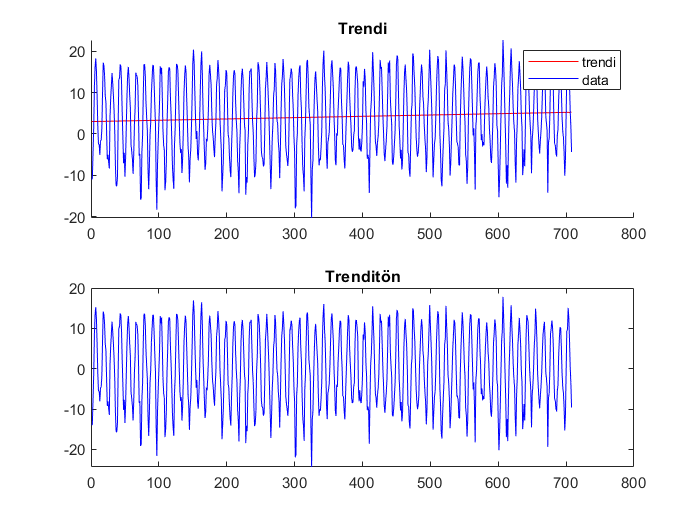


% The statistical significance will not be calculated, the trend seems
% fitting the data fine by eye


% Removing the trend

temp_detrended = temp-trend;

figure(4)
subplot(2,1,2)
plot(temp_detrended,'b')
title('Trenditön')


% validating the trend

temp_m = [];
n = 1;
m = 12;
for i = 1:a;
    temp_m(i) = mean(temp(n:m));
    n = n+12;
    m = m+12;
end

figure
hold on
plot(temp_m,'b')
title('Vuosittainen keskilämpötila')

Y_m = temp_m';
X_m = [ones(length(temp_m),1) [1:length(temp_m)]'];

b_m = X_m\Y_m

b_m =     3.0423
    0.0357


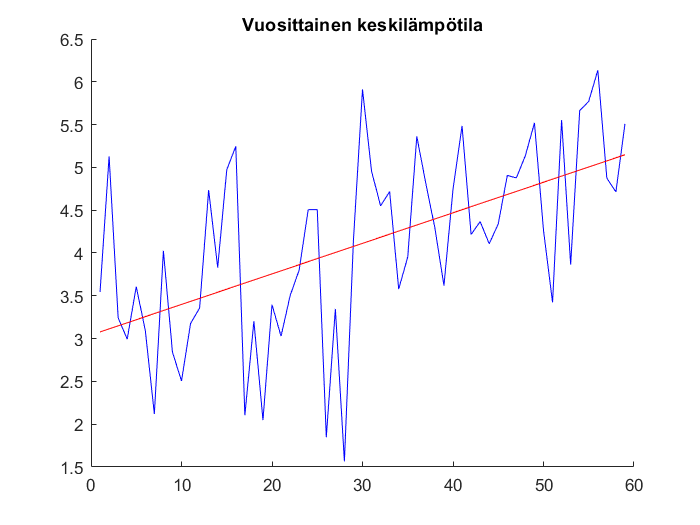

trend_m = X_m*b_m;

plot(trend_m,'r')


b_m(2)/12

ans = 0.0030


% Annual trend is same than monthly


## Removing seasonality

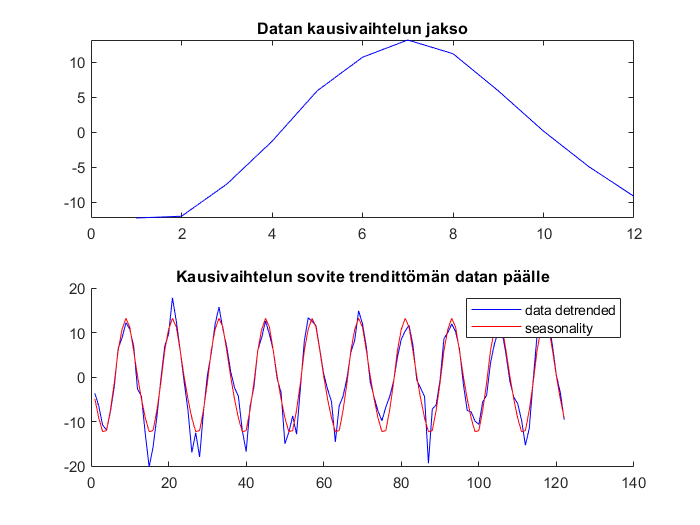

%% DECOMPOSITION-SARMA (signal/seasonality)
% calculating seasonality
% p = period of seasonality, because there is 12 months in year, can be
% assumed that the period of seasonality is 12 months

p = 12;

% one period
for i=1:p

    seasonality(i) = mean(temp_detrended(i:p:end));

end

figure
subplot(2,1,1)
plot(seasonality,'b')
title('Datan kausivaihtelun jakso')

% multiplying seasonality to whole length of the data
seas = repmat(seasonality',[a 1]);
subplot(2,1,2)
hold on
plot(temp_detrended((end-a2*12-1):end,:),'b')
plot(seas((end-a2*12-1):end,:),'r')
title('Kausivaihtelun sovite trendittömän datan päälle')
legend('data detrended', 'seasonality')

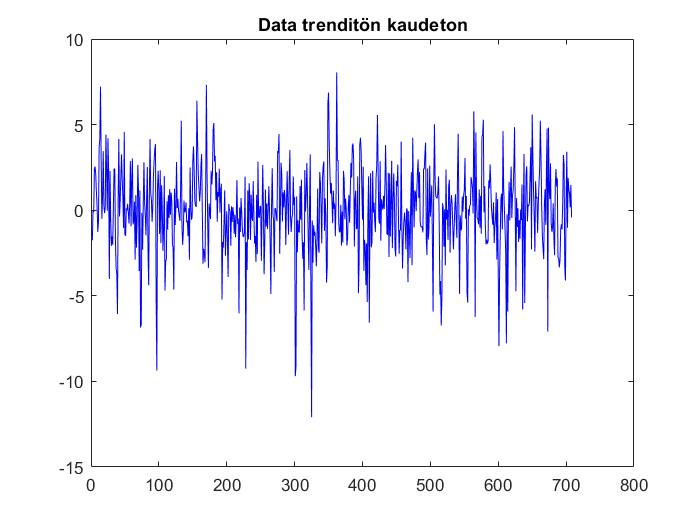

% seasonality seems to fit to data's last 10-year-period


% Removing seasonality from detrended data
temp_deseas=temp_detrended-seas;
figure
plot(temp_deseas,'b')
title('Data trenditön kaudeton')

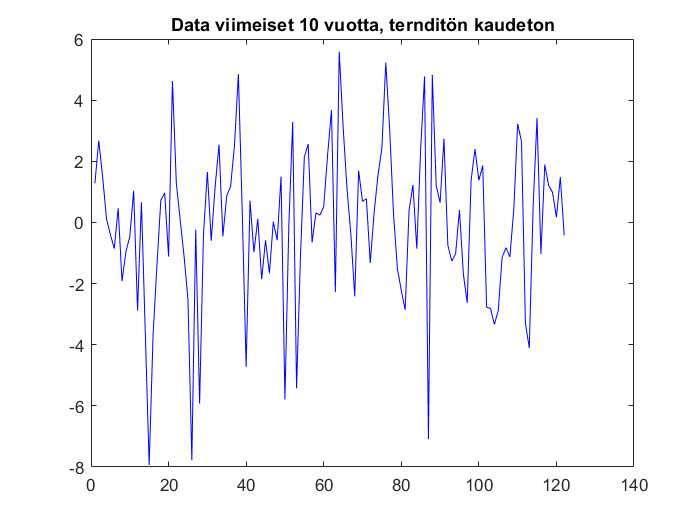


figure
plot(temp_deseas((end-a2*12-1):end,:),'b')
title('Data viimeiset 10 vuotta, ternditön kaudeton')

## Stationarity

%% DECOMPOSITION-SARMA (stationarity)

% kpsstest: does H0, sample is not stationarity its place, 1 = yes, 0 = no

% 1st difference of data
dItemp = diff(temp_deseas);

[h,pVal] = kpsstest(temp_deseas)

h = logical
   0


pVal = 0.1000

[h,pVal] = kpsstest(dItemp)

h = logical
   0


pVal = 0.1000


% adftest: 1 = stationary, 0 = nonstationary

[h,pVal] = adftest(temp_deseas)

h = logical
   1


pVal = 1.0000e-03

[h,pVal] = adftest(dItemp)

h = logical
   1


pVal = 1.0000e-03


% the detrended, deseasonal data is stationarity
% actions not needed'


## Definying model parameters

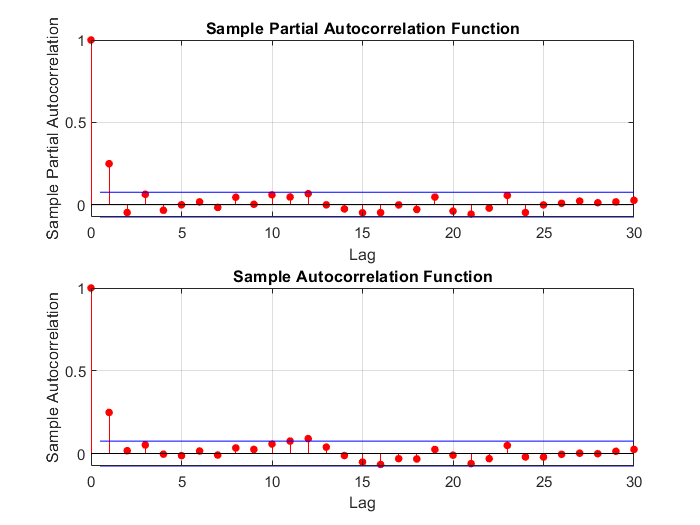

%% DECOMPOSITION-SARMA (SARMA parameters definying)
figure
% AR, (SAR)
subplot(2,1,1)
parcorr(temp_deseas,30)
% MA, (SMA)
subplot(2,1,2)
autocorr(temp_deseas,30);


% from ACF and PACF figures the best model will have p either 0 or 1, q
% either 0 or 1, Q either 0 or 1

% d,D,P = 0

% possible models: ARMA(1,1), AR(1), MA(1), SARIMA(1,0,1)(0,0,1)_12, SARIMA(1,0,0)(0,0,1)_12 or SARIMA(0,0,1)(0,0,1)_12

% the model chosen is SARIMA(0,0,1)(0,0,1)_12 since its AIC was the best
% according to MATLAB econometric modeler

## Definying of $\theta$ and $\Theta$ theoretical values

%% DECOMPOSITION-SARMA (SARMA parameters theoretical values)
% ensi arvauksen laskeminen
temp_mod = temp_deseas;

r = autocorr(temp_deseas,12);
r = r(2:end);

% t1 = theta1, ct1 = capital_theta1
syms t1 ct1



$$r_1 =\frac{-\theta_1 }{1+\theta_1 },\;\mathrm{in}\;\mathrm{condition}\;-1<\theta_1 <1$$



$$r_{12} =\frac{-\Theta_1 }{1+\Theta_1 },\;\mathrm{in}\;\mathrm{condition}-1<\Theta_1 <1$$


% theta1_0 = theoretical theta1, capital_theta1_0 = theoretical
% capital_theta1

theta1_0 = solve(r(1) == -t1/(1+t1^2));
theta1_0 = double(theta1_0);
theta1_0 = theta1_0(2)

theta1_0 = -0.2660


capital_theta1_0 = solve(r(12) == -ct1/(1+ct1^2));
capital_theta1_0 = double(capital_theta1_0);
capital_theta1_0 = capital_theta1_0(2)

capital_theta1_0 = -0.0908

## Iteration of best $\theta$- and $\Theta$-values

%% DECOMPOSITION-SARMA (SARMA parameters values iteration)

% definying necessary first 13 data-model residual values zeros
e = zeros(13,1);

% setting the first guess for theta1 and capital_theta1 values as
% theoretical value of the parameters
x1 = theta1_0;
x2 = capital_theta1_0;
coeff =[];
coeff_c = [];
RSS = [];
z = 1;

% desimal accuracy of best parameters
d_accuracy = 4;

% iteration by minimizing RSS
for l = 1:d_accuracy-1
    
    x1 = [x1-0.5*z:0.01*z:x1+0.5*z]';
    x2 = [x2-0.5*z:0.01*z:x2+0.5*z]';

for m = 1:length(x1)
    
    coeff(1) = x1(m);
    
for n = 1:length(x2)
    
    coeff(2) = x2(n);
    
            for i = 13:length(temp_mod)
                ARMA_coeff(i) = - coeff(1)*e(end) - coeff(2)*e(end-11) + coeff(1)*coeff(2)*e(end-12);
                e(i) = temp_mod(i) - ARMA_coeff(i);
            end
            
            e = zeros(13,1);
            RSS(end+1) = sum((temp_mod-ARMA_coeff').^2);
            
            coeff_c(end+1,:) = [coeff(1) coeff(2)];

end


end

f = find(RSS == min(RSS));
x1 = coeff_c(f,1);
x2 = coeff_c(f,2);

z = z/10;

end


f = find(RSS == min(RSS));

coeff_c(f,:);

% The best parameters defined
x1 = coeff_c(f,1);
x2 = coeff_c(f,2);


## Creating ${SARIMA\left(0,0,1\right)\left(0,0,1\right)}_{12}$-model for white noise

%% DECOMPOSITION-SARMA (SARIMA(0,0,1)(0,0,1)_12 for white noise)
% setting theta1 and capital_theta1 as the best parameter values
theta1 = x1

theta1 = -0.2609

capital_theta1 = x2

capital_theta1 = -0.0831

### The model of white noise


$${\hat{a} }_t =-\theta_1 \varepsilon_{t-1} -\Theta_1 \varepsilon_{t-12} +\theta_1 \Theta_1 \varepsilon_{t-13}$$


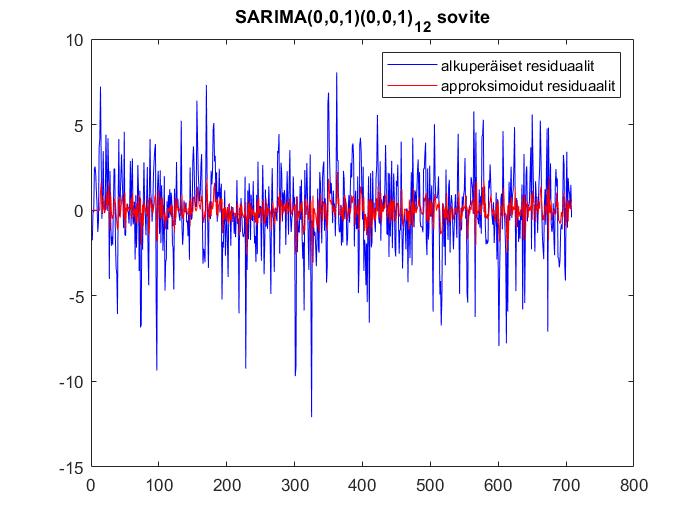

% creating the model by loop
temp_mod = temp_deseas;
e = zeros(13,1);

for i = 13:length(temp_mod);
    ARMA_p(i) = - theta1*e(end) - capital_theta1*e(end-11) + theta1*capital_theta1*e(end-12);
    e(end+1) = temp_mod(i) - ARMA_p(i);
end

% plotting the model against the white noise process
figure
plot(temp_mod,'b')
hold on
plot(ARMA_p,'r')
title('SARIMA(0,0,1)(0,0,1)_1_2 sovite')
legend('alkuperäiset residuaalit','approksimoidut residuaalit')


% goodness of the white noise process fit
RSS = sum((temp_mod-ARMA_p').^2)

RSS = 4.1304e+03

RMSE = (sqrt(mean((temp_mod-ARMA_p').^2)))

RMSE = 2.4154

## Model creation

%% DECOMPOSITION-SARMA (model creation, reverse decomposition)

Since decomposition was defined as:


$$\mathit{\mathbf{timeseries}}=\mathit{\mathbf{trend}}+\mathit{\mathbf{seasonality}}+\mathit{\mathbf{white}}\;\mathit{\mathbf{noise}}$$


and the white noise was modeled by ${SARIMA\left(0,0,1\right)\left(0,0,1\right)}_{12}$, will the ultimate model be:


$$\mathit{\mathbf{model}}=\mathit{\mathbf{trend}}+\mathit{\mathbf{seasonality}}+$$

$${\mathit{\mathbf{SARIMA}}\left(0,0,1\right)\left(0,0,1\right)}_{12}$$


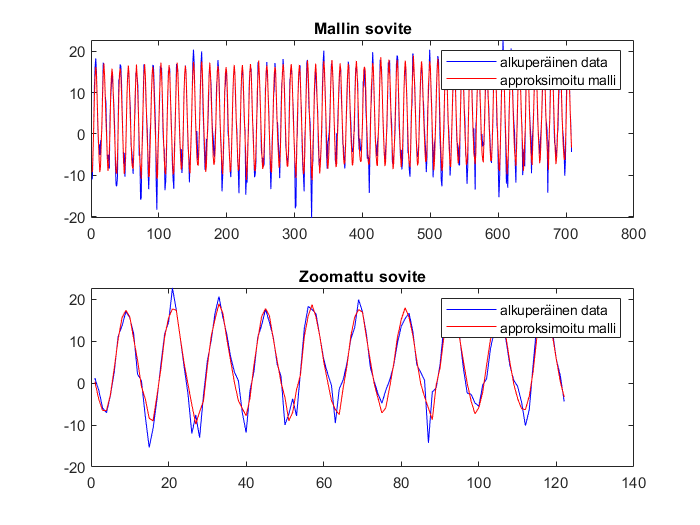

% the ultimate model
temp_model = trend + seas + ARMA_p';

% plotting the model and 10 years zoomed model
figure
hold on
subplot(2,1,1)
plot(temp,'b')
hold on
plot(temp_model,'r')
legend('alkuperäinen data','approksimoitu malli')
title('Mallin sovite')

subplot(2,1,2)
plot(temp((end-a2*12-1):end,:),'b')
hold on
plot(temp_model((end-a2*12-1):end,:),'r')
legend('alkuperäinen data','approksimoitu malli')
title('Zoomattu sovite')


% goodness of the model
RSS = sum((temp-temp_model).^2)

RSS = 4.1304e+03

RMSE = (sqrt(mean((temp-temp_model).^2)))

RMSE = 2.4154

## Forecasting white noise 

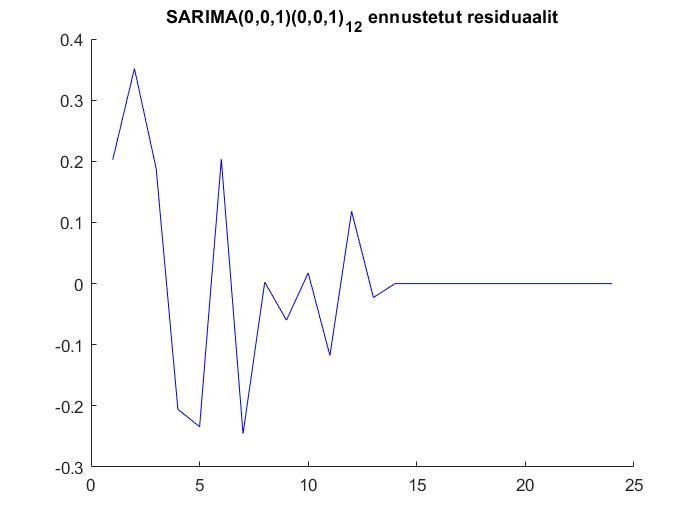

%% DECOMPOSITION-SARMA (white noise forecast)
e = e;

% starting forecasting white noise with last errorterms from created white
% noise model
for i = 1:12*a_valid;
    ARMA_f(i) =  + theta1*e(end) + capital_theta1*e(end-11) + theta1*capital_theta1*e(end-12);
    e(end+1) = 0;
end

% plotting white noise forecast
figure
hold on
title('SARIMA(0,0,1)(0,0,1)_1_2 ennustetut residuaalit')
plot(ARMA_f,'b')


fore_res = ARMA_f';


## Model forecast

%% DECOMPOSITION-SARMA (model forecast)

% forecasting trendline
hor = 12*a_valid;
n = length(temp_mod);
Xf = [ones(hor,1) (n+1:n+hor)'];

fore_trend = Xf*b;

% future seasonality
fore_seas = repmat(seasonality',[a_valid,1]);

% forecast
% reverse decomposition
% F = T + S + R
forecast = fore_trend + fore_seas + fore_res;

RSS = sum((temperature(end-12*a_valid+1:end)-forecast).^2)

RSS = 171.9506

RMSE = sqrt(mean((temperature(end-12*a_valid+1:end)-forecast).^2))

RMSE = 2.6767


error_rate = (RMSE-2.4154)/2.4154

error_rate = 0.1082

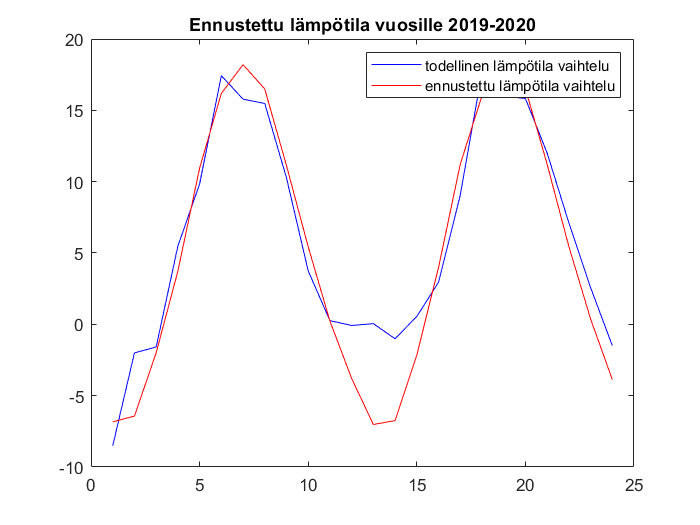


% plotting the model forecast
figure
plot(temperature(end-12*a_valid+1:end),'b')
hold on
plot(forecast,'r')
title('Ennustettu lämpötila vuosille 2019-2020')
legend('todellinen lämpötila vaihtelu','ennustettu lämpötila vaihtelu')

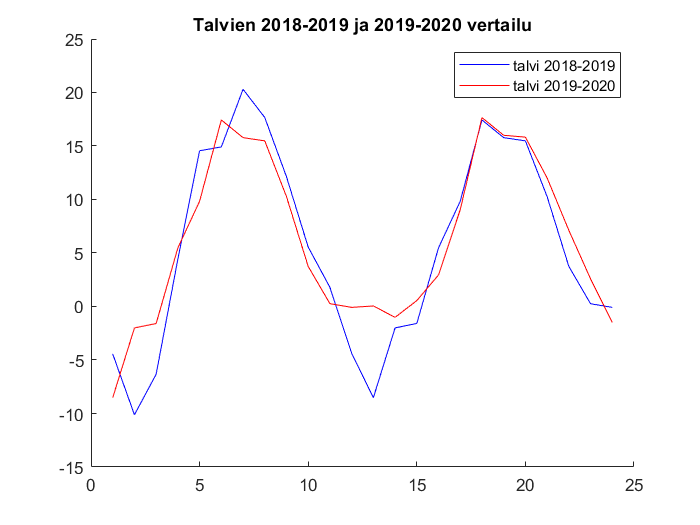


% comparing winters 2018-2019 and 2019-2020
figure
hold on
plot(temperature(end-12*(a_valid+1)+1:end-12),'b')
plot(temperature(end-12*a_valid+1:end),'r')
title('Talvien 2018-2019 ja 2019-2020 vertailu')
legend('talvi 2018-2019', 'talvi 2019-2020')

## Background functions

%% BACKGROUND FUNCTIONS
%% DATA LOADING AND GENERATING MISSING DATAPOINTS
% The following code works only with spesific data

function temp_fixeddata_ready_12=d4ta12(workbookFile, sheetName, dataLines);
[temperature,missingindexes]=d4ta365(workbookFile, sheetName, dataLines);
% sorting daily datapoints for monthly
% 31 days: jan, mar, may, jul, aug, oct, dec
% 30 days: apr, jun, sep, nov
% 28 day: feb

% 12 months per year

% 61 years of datapoints

% sorting data by years
temp_a=reshape(temperature,[365 61]);

% month's dimensions 1:31, 32:59, 60:90, 91:120, 121:151, 152:181, 182:212, 213:243,
% 244:273, 274:304, 305:334, 335:365

temp_mean=zeros(12,61);

% looping mean temperatures for every month in 61 years of data
for i=1:61
    temp_mean(1:12,i) = [mean(temp_a(1:31,i)) ; mean(temp_a(32:59,i)) ; mean(temp_a(60:90,i)) ; mean(temp_a(91:120,i)) ; mean(temp_a(121:151,i)) ;...
        mean(temp_a(152:181,i)) ; mean(temp_a(182:212,i)) ; mean(temp_a(213:243,i)) ; mean(temp_a(244:273,i)) ; ...
        mean(temp_a(274:304,i)) ; mean(temp_a(305:334,i)) ; mean(temp_a(335:365,i))];

end

% sorting back
temp_fixeddata_ready_12 = reshape(temp_mean,[numel(temp_mean),1]);

% missing values

% targeting months that include estimates created in place of original missing values
missing_values_whole_index = zeros(length(temperature),1);
% setting missing datapoints as 1 others as 0
missing_values_whole_index(missingindexes) = 1;

% only months with missing indexes will get values > 0
temp_b = reshape(missing_values_whole_index,[365 61]);
for i=1:61
    temp_indsnan(1:12,i) = [mean(temp_b(1:31,i)) ; mean(temp_b(32:59,i)) ; mean(temp_b(60:90,i)) ; mean(temp_b(91:120,i)) ; mean(temp_b(121:151,i)) ;...
        mean(temp_b(152:181,i)) ; mean(temp_b(182:212,i)) ; mean(temp_b(213:243,i)) ; mean(temp_b(244:273,i)) ; ...
        mean(temp_b(274:304,i)) ; mean(temp_b(305:334,i)) ; mean(temp_b(335:365,i))];

end

% indexes for months including estimates for original missing values
index = find(temp_indsnan > 0);
temp_original = temp_fixeddata_ready_12;
% setting months including estimates for original missing values as nan
temp_original(index) = NaN;

e = [1:length(temp_fixeddata_ready_12)]';

real_ind = setdiff(e,index);
temp_estim = temp_fixeddata_ready_12;
% only estimated months
temp_estim(real_ind) = NaN;

% plotting

figure
hold on
subplot(3,1,1)
plot(temp_original,'b')
title('Kuukausittainen korjaamaton data')
subplot(3,1,2)
plot(temp_fixeddata_ready_12(350:500),'b')
hold on
plot(temp_estim(350:500),'r-')
title('Kuukausittainen korjattu data katkenneesta kohdasta')
subplot(3,1,3)
plot(temp_fixeddata_ready_12,'b')
title('Kuukausittainen korjattu data')

end


function [temp_fixeddata_ready_365,isnan_ind] = d4ta365(workbookFile, sheetName, dataLines);

% timeseries starts 01:01:1960 and ends 31:12:2020
temperature_data = importfile(workbookFile, sheetName, dataLines);

% the last index number of timeseries 22006 does not match supposed last
% index number of 61 year time period. Timeserie cannot be complited

% resolving the error

% possible dublicate data points from same days
Klo=table2array(temperature_data(:,4));
find(Klo == '00:00');
setdiff(find(Klo == '00:00'),1:22006);

% clarifying which years have errors
year = table2array(temperature_data(:,1));
for i=1960:2020
    a = find(year == [i]);
    b(i-1959) = length(a);
end

[~,index] = setdiff(b,[366 365]);
% years 1995,1996 and 2003 are deficient

% sorting index flowing as days starting from year 0
day = table2array(temperature_data(:,3));
month = table2array(temperature_data(:,2));
ind = datenum(year,month,day);

% modifying index (ind) starting at 1 as the first point of timeseries and
% excluding the gaps caused by missing values
% the index shoul end at 61*365+16, as 16 is the amont of leap days at the
% time period
ind = ind-ind(1)+1;

% identifying formerly missing indexes
missingindexes = setdiff(1:ind(end),ind);

% fixing data as the index is compelite and missing values are marked as
% nan
temp_coeff = ones(365*61+16,1);
temp_coeff(missingindexes) = NaN;

temp_wrong_index = table2array(temperature_data(:,6));
n=1;
for i=1:365*61+16

    if temp_coeff(i) == 1;
        temp_original(i,1) = temp_wrong_index(n);
        n=n+1;
    else
        temp_original(i,1) = NaN;
    end

end


% plotting data to confirm points of discontinuity by eye
figure
plot(temp_original,'b')
title('Alkupräinen data')
ylabel('Lämpötila')
xlabel('Aika päivinä sarjan alusta')
% gaps to be filled seems to be at least 2, which the other gap is very
% significant, nearly one year period
% the gaps are around 13000:14000 and 15000:16000 on index

% the points of discontinuity has to be replaced with created estimated values

% compensatory datapoints will be defined as mean between the same
% datapoint from previous year and the data point from following year
for i=1:365*61+16

    if find(isnan(temp_original(i))) == 1;
        temp_fixeddata_notready_365(i,1) = mean([temp_original(i-365) temp_original(i+365)]);
    else
        temp_fixeddata_notready_365(i,1) = temp_original(i);
    end

end

% plotting fixed data
figure
hold on
subplot(2,1,1)
plot(temp_original(10000:16000),'b')
title('Alkuperäinen data katkenneesta kohdasta')
subplot(2,1,2)
plot(temp_fixeddata_notready_365(10000:16000),'b')
title('Korjattu data katkenneesta kohdasta')

% created datapoints are not perfect, but will do

% removin leap years feb 29th data points

% leap years appear in every 4th year, year 2000 was leap year, so 1960 and
% 2020 were also leap years

% removing leap years from the data so that the period of the data's signal
% was 365 constant
% removed days are every feb 29th starting from year 1960, ending to 2020,
% so the index number of the first removed leap day is 30+29, the next is
% 30+29+(4*365+1)*1 and the next is 30+29+(4*365+1)*2

for i=1:16
    index(i) = 30+29+(4*365+1)*(i-1);
end

index_diff = setdiff(1:length(temp_fixeddata_notready_365),index);
% choosing the index without leap days
temp_fixeddata_ready_365 = temp_fixeddata_notready_365(index_diff);

% plotting

isnan_ind = find(isnan(temp_original));

c = zeros(length(temp_fixeddata_notready_365),1);
c(isnan_ind) = 1;

lampotila_isnan_inverse = c.*temp_fixeddata_notready_365;
isnan_inverse_ind = find(lampotila_isnan_inverse==0);

lampotila_isnan_inverse(isnan_inverse_ind) = NaN;


figure
hold on
subplot(3,1,1)
plot(temp_original,'b')
title('Alkuperäinen data')

subplot(3,1,2)
hold on
plot(temp_original(11000:16000),'b')
plot(lampotila_isnan_inverse(11000:16000),'r')
title('Katkenneen kohdan korjaus')

subplot(3,1,3)
plot(temp_fixeddata_notready_365,'b')
title('Korjattu data')


end


%% Matlab's autofunction to downloading the data
function VuodenaikadataLappeenrannanlentokenttS2 = importfile(workbookFile, sheetName, dataLines)
%IMPORTFILE Import data from a spreadsheet
%  VUODENAIKADATALAPPEENRANNANLENTOKENTTS2 = IMPORTFILE(FILE) reads data
%  from the first worksheet in the Microsoft Excel spreadsheet file
%  named FILE.  Returns the data as a table.
%
%  VUODENAIKADATALAPPEENRANNANLENTOKENTTS2 = IMPORTFILE(FILE, SHEET)
%  reads from the specified worksheet.
%
%  VUODENAIKADATALAPPEENRANNANLENTOKENTTS2 = IMPORTFILE(FILE, SHEET,
%  DATALINES) reads from the specified worksheet for the specified row
%  interval(s). Specify DATALINES as a positive scalar integer or a
%  N-by-2 array of positive scalar integers for dis-contiguous row
%  intervals.
%
%  Example:
%  VuodenaikadataLappeenrannanlentokenttS2 = importfile("C:\Users\Omistaja\OneDrive\MUU SHITTI\Kandin materiaali\Vuodenaika data Lappeenrannan lentokenttä.xlsx", "Havainnot", [2, 22008]);
%
%  See also READTABLE.
%
% Auto-generated by MATLAB on 02-Jun-2021 15:59:20

%% Input handling

% If no sheet is specified, read first sheet
if nargin == 1 || isempty(sheetName)
    sheetName = 1;
end

% If row start and end points are not specified, define defaults
if nargin <= 2
    dataLines = [2, 22008];
end

%% Set up the Import Options and import the data
opts = spreadsheetImportOptions("NumVariables", 6);

% Specify sheet and range
opts.Sheet = sheetName;
opts.DataRange = "A" + dataLines(1, 1) + ":F" + dataLines(1, 2);

% Specify column names and types
opts.VariableNames = ["Vuosi", "Kk", "Pv", "Klo", "Aikavyhyke", "IlmanLmptiladegC"];
opts.VariableTypes = ["double", "double", "double", "categorical", "categorical", "double"];

% Specify variable properties
opts = setvaropts(opts, ["Klo", "Aikavyhyke"], "EmptyFieldRule", "auto");

% Import the data
VuodenaikadataLappeenrannanlentokenttS2 = readtable(workbookFile, opts, "UseExcel", false);

for idx = 2:size(dataLines, 1)
    opts.DataRange = "A" + dataLines(idx, 1) + ":F" + dataLines(idx, 2);
    tb = readtable(workbookFile, opts, "UseExcel", false);
    VuodenaikadataLappeenrannanlentokenttS2 = [VuodenaikadataLappeenrannanlentokenttS2; tb]; %#ok<AGROW>
end

end
